# Práctica 4: Árboles generadores de mínimo coste

**Funciones de MATLAB empleadas**

- **readtable() **Permite leer un fichero en varios formatos (.csv, .xls, .dat, .ods, .xml, etc) y convertirlo en un formato tabla de MATLAB.

- **rmnode() **Elimina nodos de un grafo.

- **rmedge() **Elimina aristas de un grafo.

- **degree() **Calcula el grado de los nodos de un grafo.

- **numedges() **Calcula el número de aristas de un grafo.

- **quantile() **Calcula el cuantil de un vector de datos.

- **find() **Encuentra los índices dentro de un vector que cumplen ciertas propieades.

- **minspantree() **Árbol generador de mínimo coste.

En esta práctica aplicaremos la teoría de grafos para determinar las zonas de influencia de un determinado pueblo/ciudad sobre sus pueblos/ciudades vecinas.

**Borrón y cuenta nueva!!**

clc, clear, close all

## **1. Lectura de datos**

En el 2005 se realizó una encuesta de movilidad en la comunidad autónoma de Castilla-La Mancha (España) en la que se preguntaba a los encuestados dónde se desplazaban a trabajar o a estudiar. En los dos siguientes ficheros con formato CSV (Comma-Separated Values) se recoge esta información.

Empezamos con el fichero municipios.csv que contiene datos demográficos de las poblaciones.

**municipios.csv  (las columnas representan las variables)**

- **cpm                 **Código del municipio.

- **nombre	        **Nombre de la población.

- **pob_2005	**Poblacion del municipio en 2005.

- **residen	**

- **trabajan	        **Personas que trabajan.

- **x	                **Coordenada UTM x de la población.

- **y                      **Coordenada UTM y de la población.

La instrucción *readtable* permite leer los datos de un CSV. Esta instrucción devuelve  un objeto tabla de MATLAB.

municipios = readtable('./datos/municipios.csv');
%% municipios.x(35); Acceder a datos, devuelve un array
%% Para devolver un valor/dato exacto municipios.nombre{3};

A continuación, vamos a ilustrar cómo acceder a algunos de los elementos del CSV importado.

% Para leer, por ejemplo, la lista de municipios, podemos acceder a la
% columna 'nombre' de la tabla, la cual contiene el nombre de todos los
% municipios. Notar, que esto devuelve un cell array:
municipios.nombre

ans = 919×1 cell array
    {'Abengibre'                 }
    {'Alatoz'                    }
    {'Albacete'                  }
    {'Albatana'                  }
    {'Alborea'                   }
    {'Alcadozo'                  }
    {'Alcalá del Júcar'          }
    {'Alcaraz'                   }
    {'Almansa'                   }
    {'Alpera'                    }
    {'Ayna'                      }
    {'Balazote'                  }
    {'Balsa de Ves'              }
    {'Ballestero (El)'           }
    {'Barrax'                    }
    {'Bienservida'               }
    {'Bogarra'                   }
    {'Bonete'                    }
    {'Bonillo (El)'              }
    {'Carcelén'                  }
    {'Casas de Juan Núñez'       }
    {'Casas de Lázaro'           }
    {'Casas de Ves'              }
    {'Casas-Ibáñez'              }
    {'Caudete'                   }
    {'Cenizate'                  }
    {'Corral-Rubio'              }
    {'Cotillas'                 

% Para acceder a una posición individual del cell array, usamos {fila}. Por
% ejemplo, para obtener el tercer municipio:
municipios.nombre{3}

ans = 'Albacete'

% Si queremos acceder, por ejemplo, al nombre del municipio número 12,
% usaremos:
municipios.nombre{12}

ans = 'Balazote'

% Imaginemos, que ahora queremos acceder a la población de los municipios.
% Entonces usaremos:
municipios.pob_2005

ans =          977
         603
      159518
         856
         827
         774
        1404
        1766
       24974
        2389


% Notar que esto es un vector de enteros.
% Si queremos acceder, por ejemplo, a la población del municipio número 8,
% ahora usaremos el siguiente comando:
municipios.pob_2005(8)

ans = 1766

% También se puede extraer el nombre de las poblaciones en las filas
% comprendidas entre la 4 y la 7:
municipios.nombre(4:7)

ans = 4×1 cell array
    {'Albatana'        }
    {'Alborea'         }
    {'Alcadozo'        }
    {'Alcalá del Júcar'}


Procedemos ahora a cargar el fichero translados.csv que contiene los diferentes viajes realizados.

**traslados.csv  (las columnas representan las variables)**

- **cpm_r             **Código del pueblo origen.	

- **cpm_t             **Código del pueblo destino**.**

- **traslados        **Número de viajes.

- **nombre_r       **Nombre del pueblo origen.	

- **nombre_t       **Nombre del pueblo destino.

traslados = readtable('./datos/traslados.csv');

En este caso esta tabla tiene cinco columnas que están asociadas con el id del **origen, **id del** destino, **el número de **viajes,** el nombre del pueblo de origen y el nombre del pueblo de destino. Nos centraremos en las tres primeras.

% Se puede obtener una matriz con las tres primeras columnas usando la
% siguiente línea de código:
traslados{:,["cpm_r", "cpm_t", "traslados"]}

ans =         2075        2001           1
        2034        2001           5
        2003        2001          11
        2024        2001           2
        2001        2001         181
        2023        2001           1
        2009        2002           1
        2002        2002         100
        2039        2002           1
        2021        2002           1


Observar que las tres primeras columnas de la tabla *traslados* son vectores numéricos. Las dos últimas columnas (que se corresponden con los nombres de los municipios) son cell arrays.

## 2. G1: Grafo a partir de los datos en bruto

Crea una ventana gráfica para dibujar.

figure(1)

Creamos las variables:

- **source_node  ** Nodo origen del arco.

- **target_node     **Nodo destino del arco.

- **edge_weight    **Peso del arco (número de viajes).

source_nodes = traslados.cpm_r'; % Origen, la comilla al final indica la operación transpuesta
target_nodes = traslados.cpm_t'; % Destino
edge_weights = traslados.traslados'; % Número de viajes
% Notar que traslados.cpm_r es un vector columna. Para obtener un vector fila,
% obtenemos su transpuesta con traslados.cpm_r'
% Lo mismo aplica a traslados.cpm_t y traslados.traslados.

Creamos el grafo G1:

G1 = graph(source_nodes, target_nodes, edge_weights)

G1 =   graph with properties:

    Edges: [14247×2 table]
    Nodes: [45901×0 table]


Representamos el grafo G1:

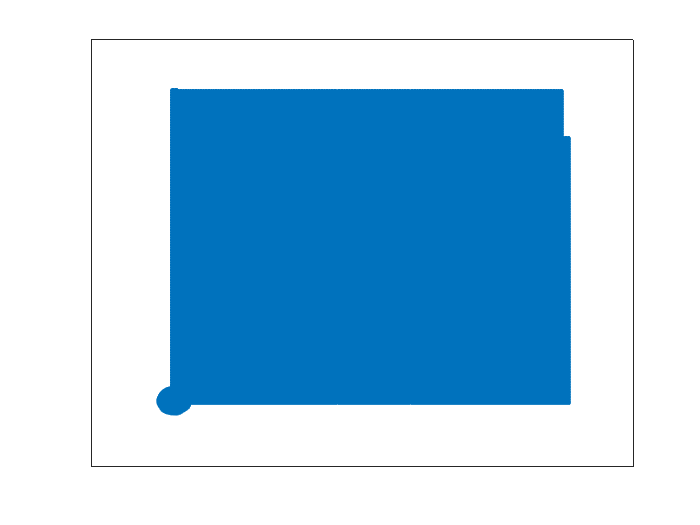

p1 = plot(G1);

## 3. G2: Grafo de Castilla-La Mancha

En el la section anterior se ha obtenido un grafo con un aspecto extraño. El motivo es que MATLAB crea todos los nodos correlativamente, añadiendo nodos inexistentes. Por ejemplo, imaginese que los nodos 45126 y 45129 aparecen en dos aristas, pero los nodos 45127 y 45128 no aparecen, entonces MATLAB asume que estos nodos existen pero no tienen aristas y los crea igualmente.

Vamos a eliminar estos nodos y dar una representación gráfica que recoja la situación geográfica de las poblaciones.

% Número de nodos en el grafo antes de eliminar los nodos sin aristas
N = numnodes(G1)

N = 45901

Eliminamos los nodos sin aristas. Para ello, primero obtenemos el grado de cada uno de los nodos del grafo.

D = degree(G1)

D =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% Seleccionamos los índices de los nodos que no tienen aristas
nodos_deleted = find(D==0)

nodos_deleted =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


% Eliminacion de los nodos que no tienen aristas
G2 = rmnode(G1, nodos_deleted)

G2 =   graph with properties:

    Edges: [14247×2 table]
    Nodes: [919×0 table]


% Número de nodos en el grafo después de eliminar los nodos sin aristas
N = numnodes(G2)

N = 919

Representamos el grafo G2. Recordar que MATLAB coloca los nodos en el plano x-y según su propio criterio, no según su localización geográfica.

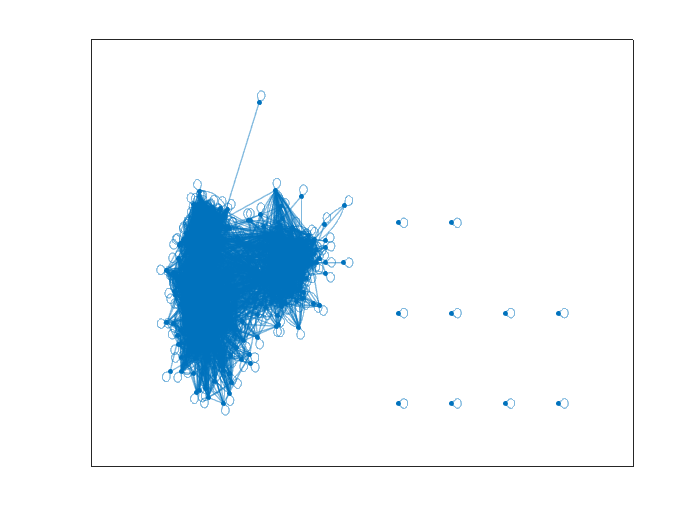

figure(2);
p2 = plot(G2);

Podemos modificar la localizacion de los nodos.

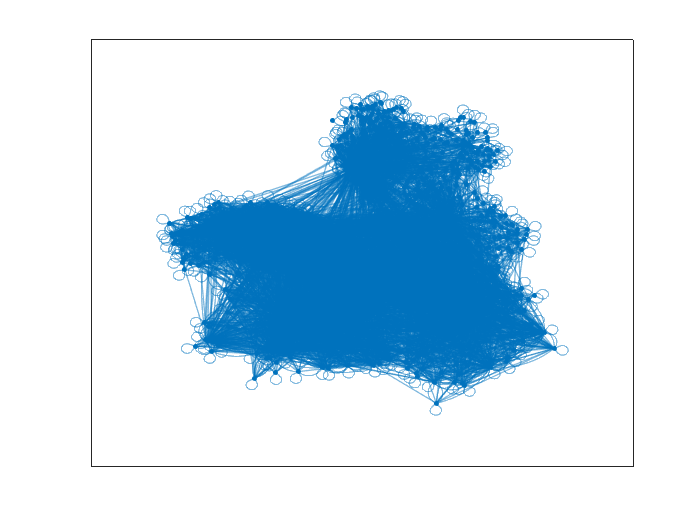

figure(3)
p2 = plot(G2);
% p2 es una estructura que contiene el dibujo del grafo con todas sus
% propiedades. Entre ellas ellas están las coordenadas de los nodos. Vamos
% a utilizar las coordenadas UTM de las poblaciones para darle el aspecto
% de mapa. Para ello:
p2.XData = municipios.x';
p2.YData = municipios.y';

Notar como el grafo generado ahora tiene una forma parecida al mapa de la comunidad de Castilla-La Mancha en España.

## 4. G3: Grafo esclarecido. Los bosques no te dejan ver los árboles.

Debido a que el número de aristas es muy elevado, vamos a considerar un grafo conteniendo solo las aristas que representen el mayor número de viajes.

 N_edges = numedges(G2) % Número de aristas del grafo actual

N_edges = 14247

La variable G2 que contiene el grafo es una variable tipo estructura. Recordar de la práctica anterior que se puede acceder a todos los datos de esta estructura. Por ejemplo:

 G2

G2 =   graph with properties:

    Edges: [14247×2 table]
    Nodes: [919×0 table]


 G2.Edges

ans = 14247×2 table
    EndNodes    Weight
    ________    ______

    1     1      181  
    1     3       11  
    1     3       74  
    1     5        2  
    1    19        1  
    1    23        1  
    1    24        2  
    1    24       37  
    1    25        1  
    1    26        1  
    1    30        1  
    1    34        5  
    1    34        1  
    1    41        2  
    1    75        1  
    1    79        4  


 G2.Edges.Weight % Vector de pesos en las aristas

ans =    181
    11
    74
     2
     1
     1
     2
    37
     1
     1


Calculamos el cuantil del 0.9 (90%) de la variable número de viajes. Es decir, nos quedaremos con el 10% de las aristas con mayor número de viajes y descartaremos las demás.

% Recordar que con G2.Edges.Weight podemos obtener el vector
% de pesos (es decir, el número de viajes entre esas ciudades).
% Podemos usar la función de MATLAB quantile para obtener el cuantil del
% 90%, es decir 0.9. Para ello, usamos:
% Mediana: Número intermedio que divide un conjunto de datos en dos
% intervalos 1, 2, 3, 4, 5, 6 -> mediana: 3, 4 -> cuantil 0,5 ó 50%
q90 = quantile(G2.Edges.Weight,0.9)

q90 = 30

Por lo tanto, el cuantil del 90% se corresponde con 30 viajes. Ahora, calculamos los índices de los arcos que tienen menos viajes que el cuantil 90% (es decir, menos de 30 viajes).

% La instrucción find encuentra los índices de un vector que cumplen una
% determinada condición, en este caso ser menor que el cuantil 90%:
idx = find(G2.Edges.Weight < q90);

Borramos del grafo G2 las aristas idx que representan el menor número de traslados.

% Borramos del grafo G2 las aristas contenidas en el vector idx
G3 = rmedge(G2, idx)

G3 =   graph with properties:

    Edges: [1431×2 table]
    Nodes: [919×0 table]


Por último, se determina que nodos no tienen aristas o son un bucle (posiblemente).

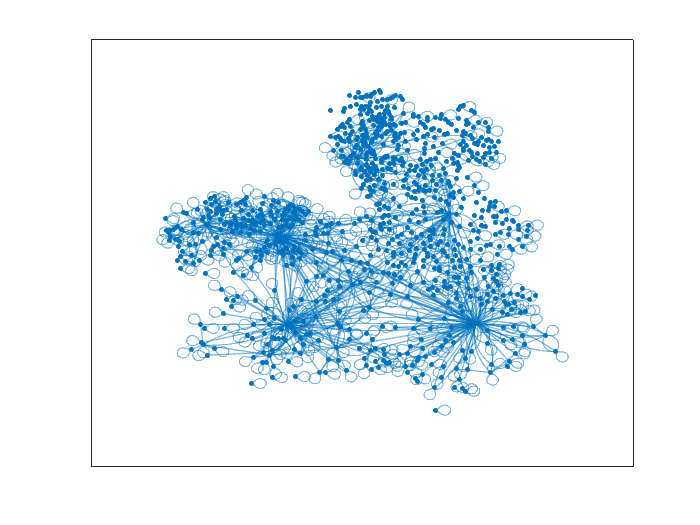

%% Visualizamos de nuevo una vez hemos limpiado parte de las aristas
figure(4)
p2_2 = plot(G3);
p2_2.XData = municipios.x';
p2_2.YData = municipios.y';

% Calculamos el grado de los nodos del grafo G3  
D = degree(G3)

D =      4
     3
   125
     2
     2
     3
     4
     4
     9
     4


% Particionamos los nodos en aquellos sin aristas o bucle (posiblemente) y
% el resto.
nodos_deleted=find(D==2| D==0)

nodos_deleted =      4
     5
    13
    16
    23
    28
    31
    32
    36
    41


nodos_restantes = find(D>2 | D==1)

nodos_restantes =      1
     2
     3
     6
     7
     8
     9
    10
    11
    12


% Borramos los nodos menos importantes
G4 = rmnode(G3, nodos_deleted)

G4 =   graph with properties:

    Edges: [1200×2 table]
    Nodes: [364×0 table]


Representamos el grafo esclarecido (con los nodos que se han eliminado)

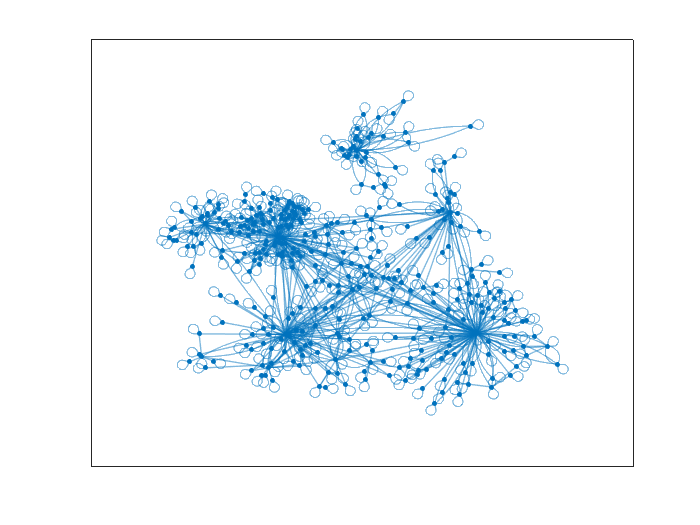

figure(4)
p4 = plot(G4);
% Cómo hemos eliminado nodos, seleccionamos coordenadas x e y de los nodos
% restantes:
p4.XData = municipios.x(nodos_restantes)';
p4.YData = municipios.y(nodos_restantes)';

## 5. G4: Árbol generador de mínimo coste. La raspa de la movilidad.

Para los grafos conexos, un árbol generador es un subgrafo que conecta todos los nodos del grafo, pero que no contiene ciclos. El árbol generador de mínimo coste es el árbol generador cuyas aristas tienen el menor peso total. MATLAB implementa una función para calcular el árbol generador de mínimo coste (o Minimum spanning tree en inglés). Esta función se denomina *minspantree(G)*. 

Mínimo número de arcos con único camino entre todos los nodos

El árbol generador de MAXIMO coste representará los desplazamientos más importantes manteniendo la conexión del grafo. El hecho de forzar a mantener la conexión hace que debamos considerar todos los nodos y de alguna manera sepamos todas las localidades a que ciudad/pueblo están conectadas. Cómo el algoritmo implementado en MATLAB encuentra el árbol generador de mínimo coste (minimizar) y nosotros queremos el árbol generador de máximo coste (maximizar), utilizamos la siguiente relación:

$\text{minimizar} \; -f(x) = \text{maximizar}\; f(x)$. Para maximizar valores los pondremos en negativo.

Por lo tanto, podemos cambiar los signos a los pesos, de tal manera que estaremos minimizando el valor negativo de los pesos, lo cual es equivalente a maximizar los pesos.

% Cambiamos el signo a los pesos:  
G4.Edges.Weight = -G4.Edges.Weight;

% Como el grafo original puede tener varias componentes conexas (al haber
% eliminado aristas), queremos calcular el árbol generador en cada una de sus
% componentes conexas, por eso elegimos la opción 'forest':
%% Devuelve T nuestro gráfo y pred grafos predecesores
[T, pred] = minspantree(G4, 'Type', 'forest');

% Esto devuelve dos valores:
% T: Devuelve el conjunto de arboles T en una estructura de grafo.
% pred: Es u vector de nodos predecesores. En este vector, la componente i
% contiene el nodo predecesor a i (que está conectado con él). Es decir,
% pred(i) devuelve el nodo predecesor a i en el árbol de mínimo coste.

Representamos el árbol generador obtenido:

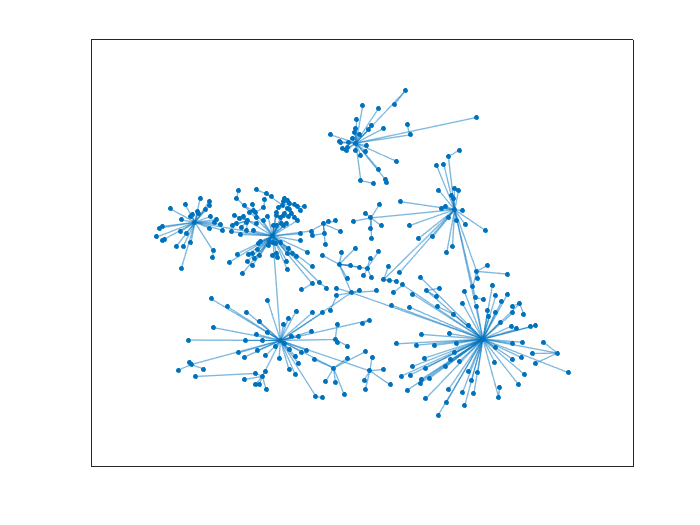

figure(5)
p5 = plot(T);
p5.XData = municipios.x(nodos_restantes)';
p5.YData = municipios.y(nodos_restantes)';

Observando el árbol generado, se muestra claramente la influencia de las capitales de provincia y Talavera de la Reina, que son las ciudades que atraen el mayor número de viajes procedentes de otros pueblos o ciudades de la región. Este árbol puede utilizarse para identificar las principales vías de comunicación en la región y actuar sobre ellas.